# Optimization - iterative method

clc;
clear;
close all;

[param, weather, route, driver] = loadData();

effLoss = load("inefficiency.mat").effLoss;
tempCF = load("temperatureCF.mat").tempCF;
velSafe = load("optimalMeanVelocity.mat").velMeanOpt_unitedStops;

cd("C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Codes\Optimization");

interestDay = datetime(2020,10,20);
enhanceFactor = 1.8;
raceDays = 5;
plotIsRequested = false;
weatherSim = weatherSimFullRace(interestDay, enhanceFactor, raceDays, plotIsRequested);

Colours for plots

colour = struct();
colour.loss = 'r';
colour.solar = 'g';
colour.battery = 'magenta';

#### Cumulative solar energy

EcumSolar = cumtrapz(weatherSim.irradiance.GtotalSec) * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total; %J

#### Battery initial energy and safe to spend energy

SoCmin = 0.1;
Ebatmax = param.battery.E0; %J
EbatSafe = Ebatmax * (1 - SoCmin); %J

## Cut only driving time

horizon_8_17 = logical(weatherSim.irradiance.driving_8_17_Sec); %conversion to logical
time_8_17 = weatherSim.irradiance.timeSec(horizon_8_17);
dayNum_8_17 = weatherSim.irradiance.dayNumSec(horizon_8_17);

timeLen_8_17 = length(time_8_17);
timeSec_8_17 = linspace(1, timeLen_8_17, timeLen_8_17)';

#### Cumulative energy

EcumSolar_8_17 = EcumSolar(horizon_8_17);
EbudgetTot_8_17 = EcumSolar_8_17 + EbatSafe;

#### Energy loss

Froll = param.constants.roll; %N
Faero_8_17 = param.constants.aero * (driver.finishLocDist ./ timeSec_8_17).^2;

Eloss_8_17 = driver.finishLocDist / effLoss * (Froll + Faero_8_17);

#### Find optimal point

timeOptCut = find(Eloss_8_17 <= EbudgetTot_8_17, 1, 'first');
fprintf('Optimal driving time: %3.2f h', timeOptCut / 3600)

Optimal driving time: 31.07 h


%adding night duration
time_nonDriving = weatherSim.irradiance.timeSec(~horizon_8_17);
numNights = floor(timeOptCut/(3600 * 9));

startNights = find(diff(horizon_8_17) == -1, numNights, 'first') - 1; %check again first and last point
endNights = find(diff(horizon_8_17) == 1, numNights, 'first');

durationSecNights = endNights - startNights;
durationHnights = durationSecNights / 3600;
totNights = sum(durationHnights);

fprintf('Total time: %3.2f h', timeOptCut / 3600 + totNights)

Total time: 44.91 h


velMeanOpt = driver.finishLocDist / timeOptCut;
fprintf('Optimal velocity: %3.2f km/h', velMeanOpt * 3.6)

Optimal velocity: 97.42 km/h

### Plot

#### Energy, irradiance vs driving time

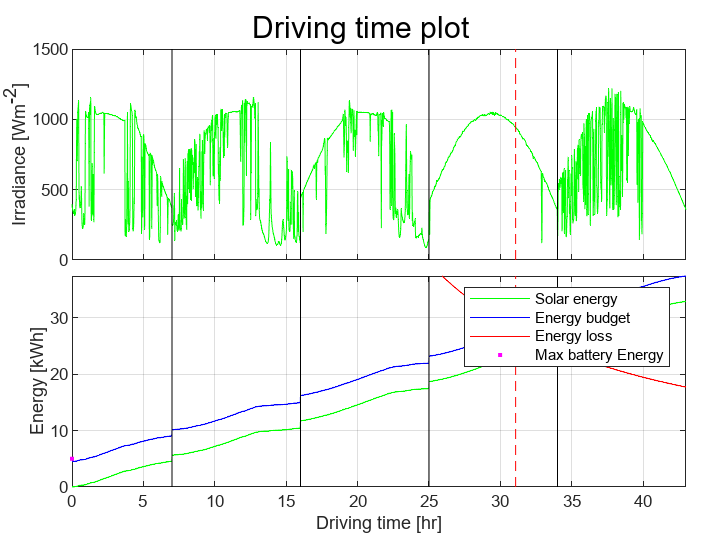

title = 'Driving time plot';
synchronizeXAxes = true;
xaxisTime = timeSec_8_17 / 3600;
nightStopHour_17 = (7 : 9 : 9*(raceDays-1))';
xlimVecTime = [0, xaxisTime(end)];
ylimVecTime = [0, J2kWh(EcumSolar_8_17(end)+EbatSafe)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisTime, weatherSim.irradiance.GtotalSec(horizon_8_17),'-','Color',colour.solar);
builder.addLines('vertical', nightStopHour_17, 'k');
builder.addLines('vertical', timeOptCut / 3600, 'r--');
builder.setYlabel("Irradiance [Wm^{-2}]");
builder.setXlim(xlimVecTime)

builder.startNewSubplot();
builder.addPlot(xaxisTime, J2kWh(EcumSolar_8_17),'-','Color',colour.solar);
builder.addPlot(xaxisTime, J2kWh(EbudgetTot_8_17),'-','Color','b');
builder.addPlot(xaxisTime, J2kWh(Eloss_8_17),'-','Color',colour.loss);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addPlot(timeOptCut / 3600, J2kWh(Eloss_8_17(timeOptCut)), 'r.', 'MarkerSize', 20)
builder.addLines('vertical', nightStopHour_17, 'k');
builder.addLines('vertical', timeOptCut / 3600, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Solar energy","Energy budget","Energy loss","Max battery Energy")
builder.setXlim(xlimVecTime)
builder.setYlim(ylimVecTime)

builder.setXlabel("Driving time [hr]");
builder.drawNow()

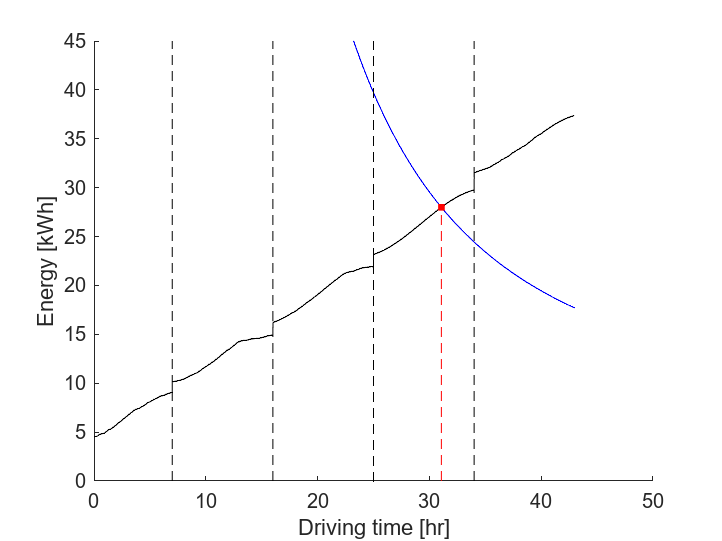

savePlots = false;
step = 32;

figure
hold on
plot(xaxisTime(1:step:end), J2kWh(EbudgetTot_8_17(1:step:end)), 'k');
plot(xaxisTime(1:step:end), J2kWh(Eloss_8_17(1:step:end)), 'b');
plot([timeOptCut, timeOptCut] / 3600, [0, J2kWh(EbudgetTot_8_17(timeOptCut,1))], 'r--')
plot(timeOptCut / 3600, J2kWh(EbudgetTot_8_17(timeOptCut)), 'r.', 'MarkerSize', 10)
plotLines(gca, 'vertical', nightStopHour_17, 'k')
ylabel("Energy [kWh]")
xlabel("Driving time [hr]")
ylim([0, 45])


if savePlots
    figureName = 'intersectionStrategy';
    latexMatlabPlotSaver(figureName, 'cleanFigure', true)
end % if

## Distance Analysis

distVec = timeSec_8_17 * velMeanOpt;

altiInterp = interp1(route.dist, route.alti, distVec);
EpotDist = param.structure.mass.total * getPhysicalConstants().g * altiInterp; %J

FaeroDist = param.constants.aero * velMeanOpt^2; %N
ElossDist = distVec / effLoss * (Froll + FaeroDist); %J

EcumSolarDist = EcumSolar_8_17;
EbudgetTotDist = EbudgetTot_8_17;

EBatDist = Ebatmax + EcumSolarDist - ElossDist; %- EpotDist
SoCdist = EBatDist / Ebatmax;

### Plot

#### Energy vs distance

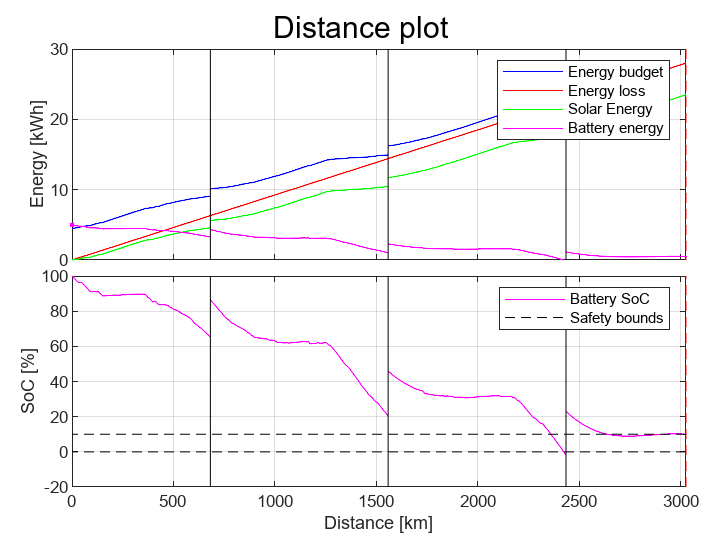

title = 'Distance plot';
synchronizeXAxes = true;
xaxisDist = distVec / 1000;
nightStopDist_17 = nightStopHour_17 * velMeanOpt * 3.6;
xlimVecDist = [0, driver.finishLocDist / 1000];
% xlimVecDist = [0, xaxisTime(end) * velMeanOpt * 3.6];
ylimVecDist = [0, 30];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisDist, J2kWh(EbudgetTotDist),'-','Color','b');
builder.addPlot(xaxisDist, J2kWh(ElossDist),'-','Color',colour.loss);
builder.addPlot(xaxisDist, J2kWh(EcumSolarDist),'-','Color',colour.solar);
builder.addPlot(xaxisDist, J2kWh(EBatDist),'-','Color',colour.battery);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.addLines('vertical', nightStopDist_17, 'k');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Energy budget","Energy loss","Solar Energy","Battery energy")
builder.setXlim(xlimVecDist)
builder.setYlim(ylimVecDist)

builder.startNewSubplot();
builder.addPlot(xaxisDist, SoCdist * 100,'-','Color',colour.battery);
builder.addLines('horizontal', 0, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.addLines('horizontal', (1 - EbatSafe / Ebatmax) * 100, 'k--');
builder.addLines('vertical', nightStopDist_17, 'k');
builder.setYlabel("SoC [%]")
builder.setLegend("Battery SoC","Safety bounds")
builder.setXlim(xlimVecDist)

builder.setXlabel("Distance [km]");
builder.drawNow()

## Iteration

#### Detection

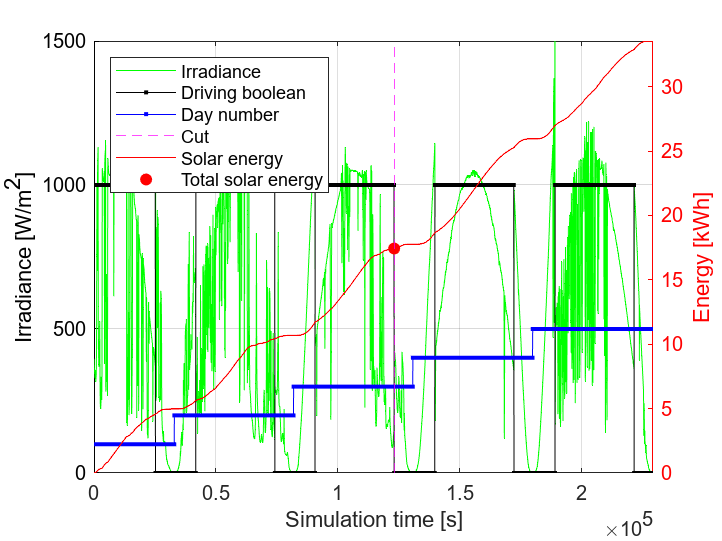

lowSoCisDetected = min(SoCdist) < SoCmin;

if lowSoCisDetected
    indexDetection = find(SoCdist == min(SoCdist));
    numDayDetection = dayNum_8_17(indexDetection);
end % if
numDayDetection = 3; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHECK AGAIN

detectionNightIndex_17 = max(find(diff(weatherSim.irradiance.driving_8_17_Sec) == -1, numDayDetection, 'first'));
Esolar_nthDay = EcumSolar(detectionNightIndex_17);

% fig = figure;
% set(fig,'defaultAxesColorOrder',[[0 0 0]; [1 0 0]]);
% yyaxis left
% hold on
% plot(weatherSim.irradiance.timeSec, weatherSim.irradiance.GtotalSec, colour.solar, 'DisplayName', 'Irradiance')
% plot(weatherSim.irradiance.timeSec, 1000 * weatherSim.irradiance.driving_8_17_Sec, '-k.', 'DisplayName', 'Driving boolean')
% plot(weatherSim.irradiance.timeSec, 100 * weatherSim.irradiance.dayNumSec, '-b.', 'DisplayName', 'Day number')
% xline(weatherSim.irradiance.timeSec(detectionNightIndex_17), 'm--', 'DisplayName', 'Cut')
% xlim([0, weatherSim.irradiance.timeSec(end)])
% ylim([0, 1500]);
% xlabel('Simulation time [s]');
% ylabel('Irradiance [W/m^2]');
% yyaxis right
% plot(weatherSim.irradiance.timeSec, J2kWh(EcumSolar), 'DisplayName', 'Solar energy')
% scatter(weatherSim.irradiance.timeSec(detectionNightIndex_17), J2kWh(Esolar_nthDay), 'ro', 'filled', 'DisplayName', 'Total solar energy')
% ylim([0, J2kWh(EcumSolar(end))]);
% ylabel('Energy [kWh]');
% clickableLegend
% legend('Location','northwest')
% grid on
% box on
% hold off

#### Safe velocity estimation

p = param.constants.roll / param.constants.aero;
q = -effLoss * (EbatSafe + Esolar_nthDay) / (seconds(hours(9*numDayDetection-2)) * param.constants.aero);
velSafe = cardanoDepressed3rd(p,q);
fprintf('Safe velocity: %3.2f km/h', velSafe * 3.6)

Safe velocity: 96.40 km/h


% velVec = linspace(0, 30, 10000);
% powerBalanceFun = velVec.^3 + p*velVec + q;
% checkSolution = interp1(velVec, powerBalanceFun, velSafe);
% figure
% hold on
% plot(velVec * 3.6, powerBalanceFun)
% scatter(velSafe * 3.6, checkSolution, 'ro', 'filled', 'DisplayName', 'Total solar energy')
% xlabel('Velocity [km/h]');
% ylabel('Energy balance function');
% grid on
% box on

distVecSafe = timeSec_8_17 * velSafe;

altiInterpSafe = interp1(route.dist, route.alti, distVecSafe);
EpotDistSafe = param.structure.mass.total * getPhysicalConstants().g * altiInterpSafe; %J

FaeroDistSafe = param.constants.aero * velSafe^2; %N
ElossDistSafe = distVecSafe / effLoss * (Froll + FaeroDistSafe); %J

EcumSolarDistSafe = EcumSolar_8_17;

EBatDistSafe = Ebatmax + EcumSolarDistSafe - ElossDistSafe; % - EpotDistSafe
SoCdistSafe = EBatDistSafe / Ebatmax;

timeSafe = driver.finishLocDist / velSafe;
fprintf('Optimal driving time: %3.2f h', timeSafe / 3600)

Optimal driving time: 31.40 h

### Plot

#### Energy vs distance

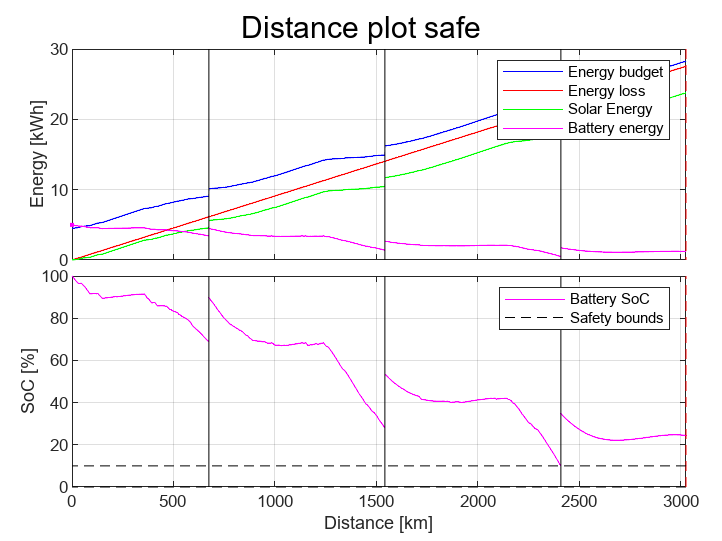

title = 'Distance plot safe';
synchronizeXAxes = true;
xaxisDist = distVecSafe / 1000;
nightStopDist_17 = nightStopHour_17 * velSafe * 3.6;
xlimVecDist = [0, driver.finishLocDist / 1000];
% xlimVecDist = [0, xaxisTime(end) * velSafe * 3.6];
% ylimVecDist = [0, max(J2kWh(ElossDistSafe))];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisDist, J2kWh(EbudgetTotDist),'-','Color','b');
builder.addPlot(xaxisDist, J2kWh(ElossDistSafe),'-','Color',colour.loss);
builder.addPlot(xaxisDist, J2kWh(EcumSolarDistSafe),'-','Color',colour.solar);
builder.addPlot(xaxisDist, J2kWh(EBatDistSafe),'-','Color',colour.battery);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.addLines('vertical', nightStopDist_17, 'k');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Energy budget","Energy loss","Solar Energy","Battery energy") %"Potential energy",
builder.setXlim(xlimVecDist)
builder.setYlim(ylimVecDist)

builder.startNewSubplot();
builder.addPlot(xaxisDist, SoCdistSafe * 100,'-','Color',colour.battery);
builder.addLines('horizontal', 0, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.addLines('horizontal', (1 - EbatSafe / Ebatmax) * 100, 'k--');
builder.addLines('vertical', nightStopDist_17, 'k');
builder.setYlabel("SoC [%]")
builder.setLegend("Battery SoC","Safety bounds")
builder.setXlim(xlimVecDist)

builder.setXlabel("Distance [km]");
builder.drawNow()

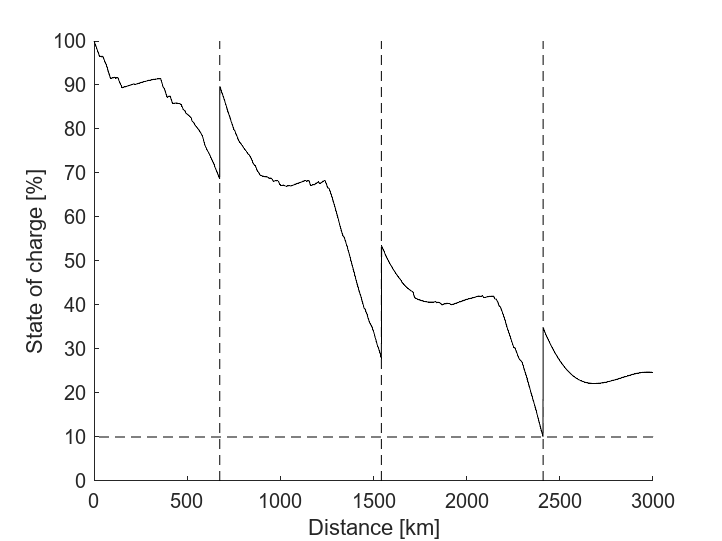

savePlots = false;
step = 32;

figure
hold on
plot(xaxisDist(1:step:end), SoCdistSafe(1:step:end) * 100, 'k');
plotLines(gca, 'vertical', nightStopDist_17, 'k--')
plotLines(gca, 'horizontal', SoCmin * 100, 'k--')
ylabel("State of charge [%]")
xlabel("Distance [km]")
xlim([0, 3000])
ylim([0, 100])


if savePlots
    figureName = 'SoCsafeStrategy';
    latexMatlabPlotSaver(figureName, 'cleanFigure', true)
end % if

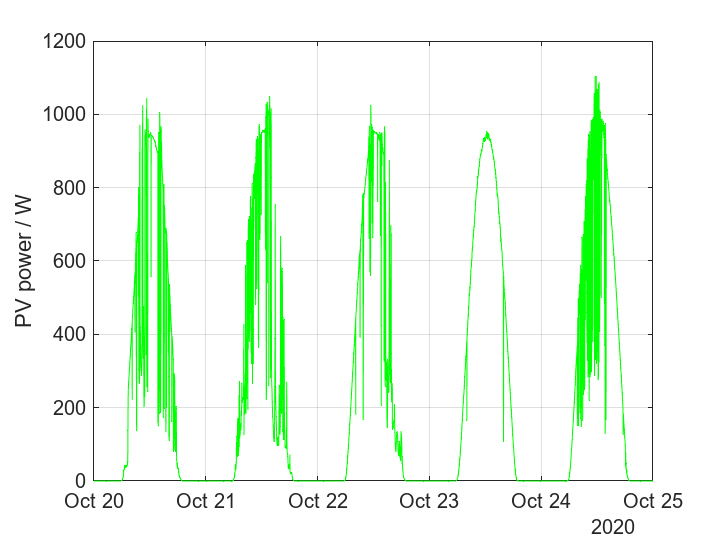

savePlots = false;

PVpower = weather.irradiance.Gtotal * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total;

figure
hold on
plot(weather.irradiance.time, PVpower,'-','Color',colour.solar);
xlim([datetime(2020,10,20,0,0,0), datetime(2020,10,25,0,0,0)])
ylim([0, 1200])
ylabel('PV power / W')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'PVpower_time';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

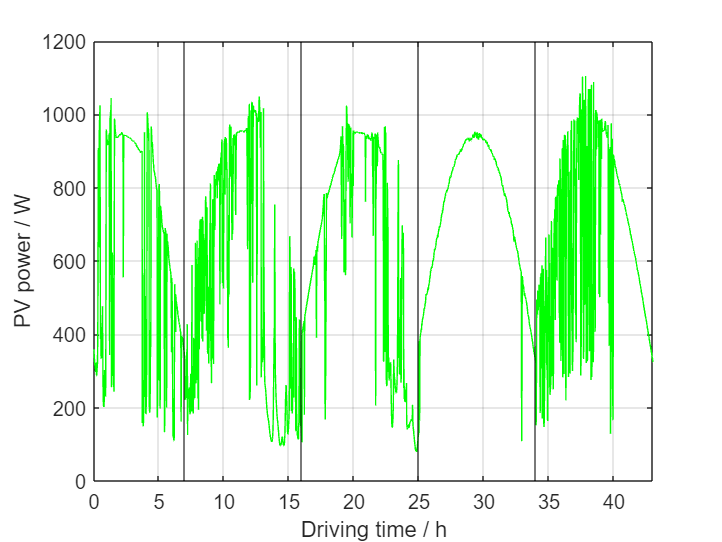

savePlots = false;

PVpowerRace = weatherSim.irradiance.GtotalSec(horizon_8_17) * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total;

figure
hold on
plot(xaxisTime, PVpowerRace,'-','Color',colour.solar);
xline(nightStopHour_17,'-','Color','k','HandleVisibility','off');
xlim([0, max(xaxisTime)])
ylim([0, 1200])
xlabel('Driving time / h')
ylabel('PV power / W')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'PVpower_timeRace';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

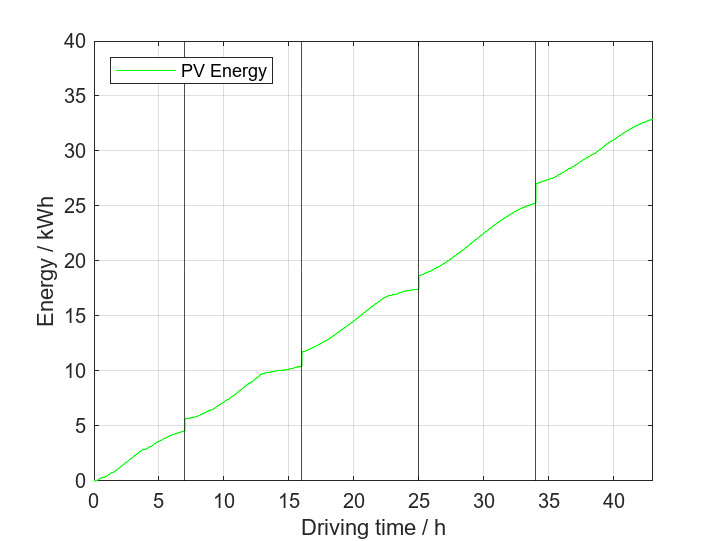

savePlots = false;

figure
hold on
plot(xaxisTime, J2kWh(EcumSolar_8_17),'-','Color',colour.solar,'DisplayName','PV Energy');
xline(nightStopHour_17,'-','Color','k','HandleVisibility','off');
xlim([0, max(xaxisTime)])
ylim([0, 40])
xlabel('Driving time / h')
ylabel('Energy / kWh')
legend('Location','northwest')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'PVenergy_timeRace';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

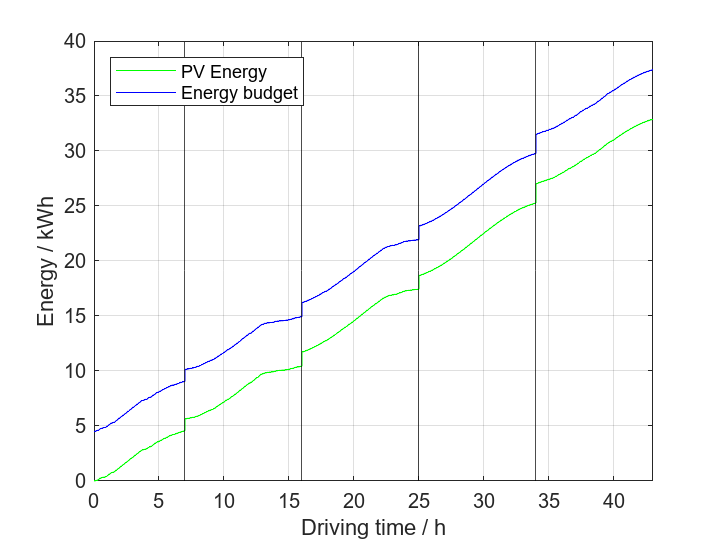

savePlots = false;

figure
hold on
plot(xaxisTime, J2kWh(EcumSolar_8_17),'-','Color',colour.solar,'DisplayName','PV Energy');
plot(xaxisTime, J2kWh(EbudgetTot_8_17),'-','Color','b','DisplayName','Energy budget');
xline(nightStopHour_17,'-','Color','k','HandleVisibility','off');
xlim([0, max(xaxisTime)])
ylim([0, 40])
xlabel('Driving time / h')
ylabel('Energy / kWh')
legend('Location','northwest')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'BudgetEnergy_timeRace';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

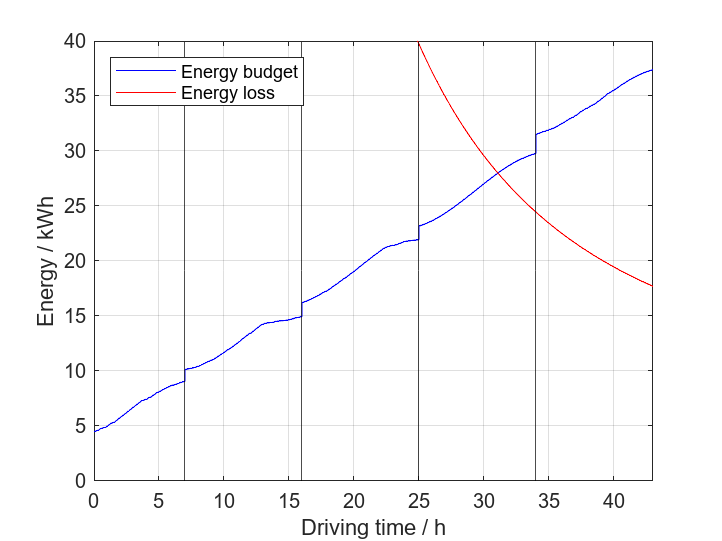

savePlots = false;

figure
hold on
plot(xaxisTime, J2kWh(EbudgetTot_8_17),'-','Color','b','DisplayName','Energy budget');
plot(xaxisTime, J2kWh(Eloss_8_17),'-','Color',colour.loss,'DisplayName','Energy loss');
xline(nightStopHour_17,'-','Color','k','HandleVisibility','off');
xlim([0, max(xaxisTime)])
ylim([0, 40])
xlabel('Driving time / h')
ylabel('Energy / kWh')
legend('Location','northwest')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'LossEnergy_timeRace';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

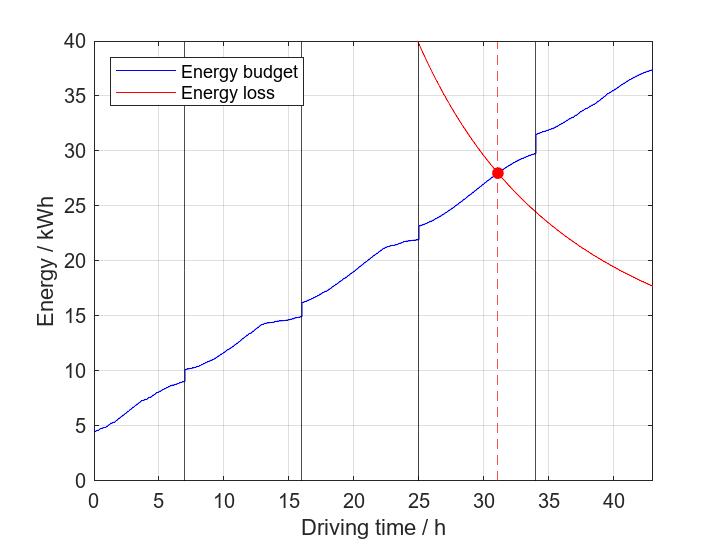

savePlots = false;

figure
hold on
plot(xaxisTime, J2kWh(EbudgetTot_8_17),'-','Color','b','DisplayName','Energy budget');
plot(xaxisTime, J2kWh(Eloss_8_17),'-','Color',colour.loss,'DisplayName','Energy loss');
plot(timeOptCut / 3600, J2kWh(Eloss_8_17(timeOptCut)), 'r.', 'MarkerSize', 20,'HandleVisibility','off');
xline(timeOptCut / 3600, 'r--','HandleVisibility','off');
xline(nightStopHour_17,'-','Color','k','HandleVisibility','off');
xlim([0, max(xaxisTime)])
ylim([0, 40])
xlabel('Driving time / h')
ylabel('Energy / kWh')
legend('Location','northwest')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'IntersectionEnergy_timeRace';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

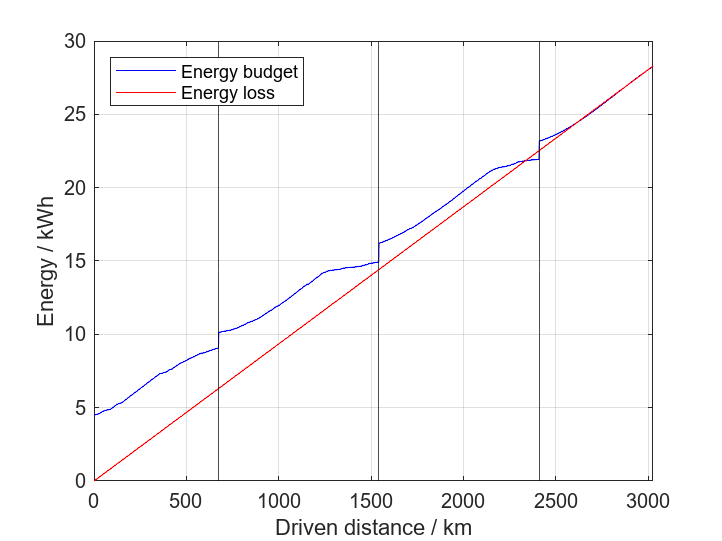

savePlots = false;

figure
hold on
plot(xaxisDist, J2kWh(EbudgetTotDist),'-','Color','b','DisplayName','Energy budget');
plot(xaxisDist, J2kWh(ElossDist),'-','Color',colour.loss,'DisplayName','Energy loss');
xline(nightStopDist_17,'-','Color','k','HandleVisibility','off');
xlim(xlimVecDist)
ylim([0, 30])
xlabel('Driven distance / km')
ylabel('Energy / kWh')
legend('Location','northwest')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'LossEnergy_dist';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

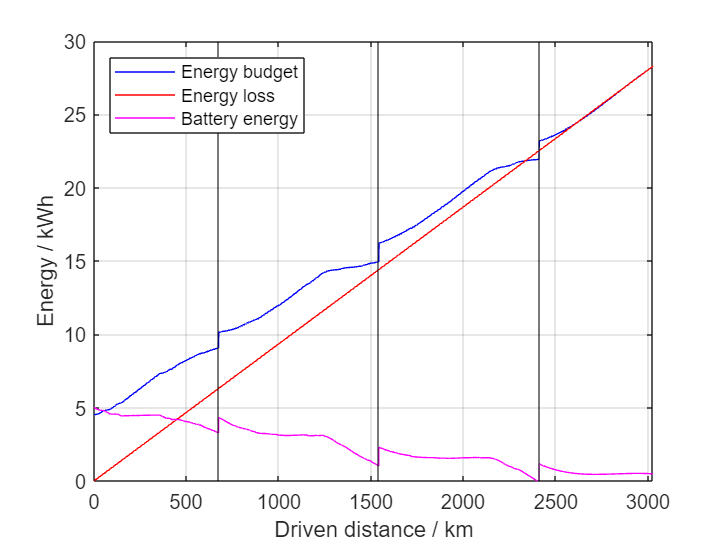

savePlots = false;

figure
hold on
plot(xaxisDist, J2kWh(EbudgetTotDist),'-','Color','b','DisplayName','Energy budget');
plot(xaxisDist, J2kWh(ElossDist),'-','Color',colour.loss,'DisplayName','Energy loss');
plot(xaxisDist, J2kWh(EBatDist),'-','Color',colour.battery,'DisplayName','Battery energy');
xline(nightStopDist_17,'-','Color','k','HandleVisibility','off');
xlim(xlimVecDist)
ylim([0, 30])
xlabel('Driven distance / km')
ylabel('Energy / kWh')
legend('Location','northwest')
box on
grid on


folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'Energies_dist';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

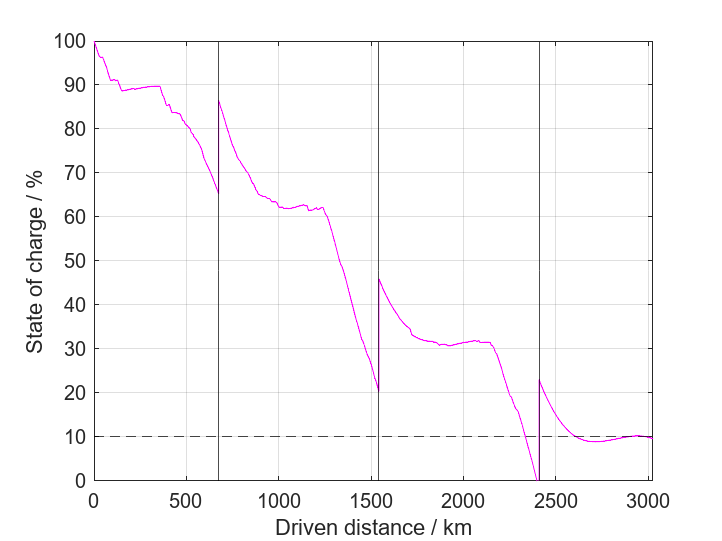

savePlots = false;

figure
hold on
plot(xaxisDist, EBatDist / Ebatmax * 100,'-','Color',colour.battery,'DisplayName','Battery energy');
xline(nightStopDist_17,'-','Color','k','HandleVisibility','off');
yline(SoCmin * 100,'k--','HandleVisibility','off');
xlim(xlimVecDist)
ylim([0, 100])
xlabel('Driven distance / km')
ylabel('State of charge / %')
box on
grid on

folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'SoC_dist';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end

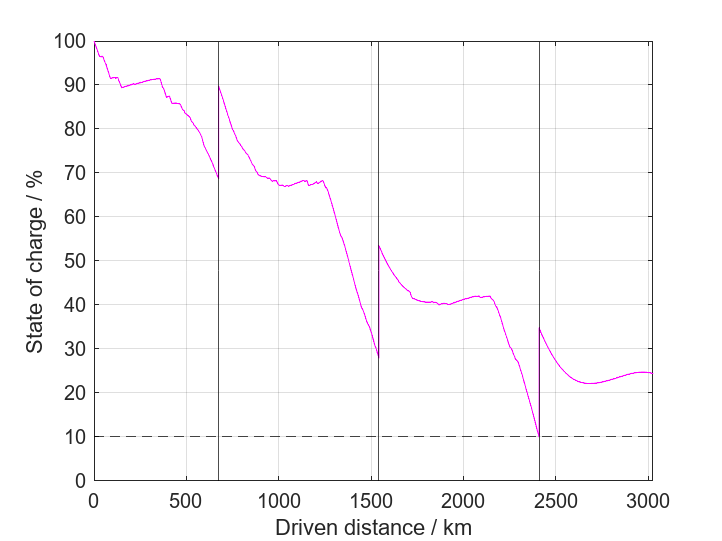

savePlots = false;

figure
hold on
plot(xaxisDist, EBatDistSafe / Ebatmax * 100,'-','Color',colour.battery,'DisplayName','Battery energy');
xline(nightStopDist_17,'-','Color','k','HandleVisibility','off');
yline(SoCmin * 100,'k--','HandleVisibility','off');
xlim(xlimVecDist)
ylim([0, 100])
xlabel('Driven distance / km')
ylabel('State of charge / %')
box on
grid on

folder_save_plots = 'C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Presentation\Final\Matlab Plots';
addpath(folder_save_plots);

if savePlots
    filename_save = 'SoCsafe_dist';
    export_fig(gcf,[char(filename_save),'.png'],'-opengl','-transparent','-r600') %for PP
    movefile([char(filename_save),'.png'], folder_save_plots)
end